load starData

[sHa,idx] = min(spectra);
lambdaHa = lambda(idx);
z = lambdaHa/656.28 - 1;
speed = z*299792.458

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


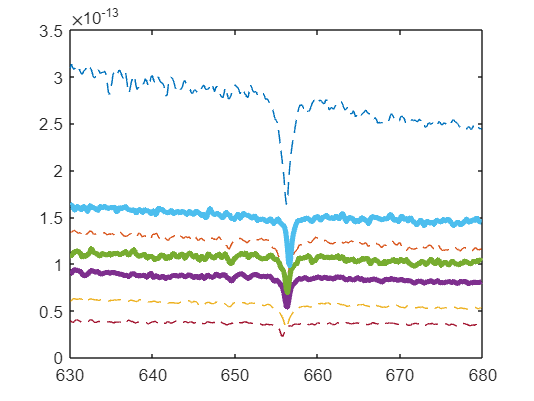

for v = 1:7
    s = spectra(:,v);

    if speed(v) <= 0
        plot(lambda,s,"--")
    else
        plot(lambda,s,"LineWidth",3) 
    end
    hold on
end
hold off

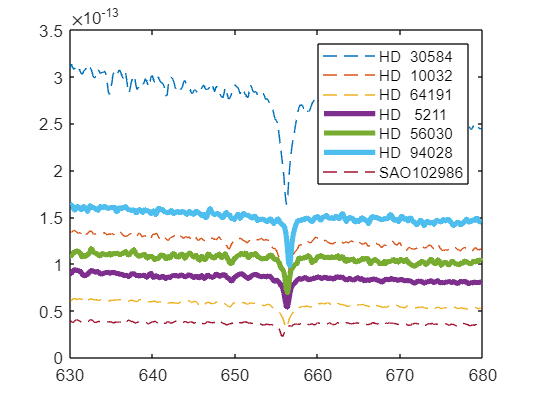

legend(starnames)

movaway = starnames(speed > 0) 

movaway = 3×1 string array
    "HD   5211"
    "HD  56030"
    "HD  94028"
